## **SIO 207A Midterm Project**

**Ruipu Ji**

#### Problem I.

% Initialization and default plot settings.
clear; clc; close all;

set(0, 'DefaultAxesFontSize', 10);
set(0, 'DefaultTextFontSize', 10);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');

A complex number series is generated with a given length *N*. The real part of the complex numbers are limited within the range of [-*R*, *R*] and the imaginary part of the complex numbers are limited within the range of [-*I*i, *I*i]. The coefficients *N*, *R* and *I* are given from the inputs.

% Define the inputs.
N = 8192; % N = Length of the complex number series.
R = 100; % The real part of the complex numbers are limited within the range of [-R, R].
I = 100; % The imaginary part of the complex numbers are limited within the range of [-Ii, Ii].

% Define the random complex number series.
RealPart = -R + 2*R*rand(N,1);
ImagPart = -I + 2*I*rand(N,1);
ComplexNumber = RealPart + ImagPart*(1i);

Multiple window sequences are defined including: (1) rectangluar window, (2) triangular window, (3) Hanning window, (4) Hamming window, and (5) Kaiser-Bessel window (*α* = 2.5 or *β* = *πα* = 7.85). The lengths of the window sequences are the same as the length *N* of the complex series.

% Generate window sequences with the given sequence length N.
RectangularWindow = rectwin(N); % Rectangular window.
TriangularWindow = triang(N); % Triangular window.
HanningWindow = hann(N); % Hannning window.
HammingWindow = hamming(N); % Hamming window.
KaiserBesselWindow = kaiser(N, 7.85); % Kaiser-Bessel window (alpha = 2.5 or beta = alpha*pi = 7.85).

Function 'Window_fft' is used to window the sequence, then calculate Fourier transform or inverse Fourier transform for the windowed data.

WindowSequences = [RectangularWindow, TriangularWindow, HanningWindow, HammingWindow, KaiserBesselWindow];
OutputData = zeros(N, 3*size(WindowSequences,2));

for i = 1:size(WindowSequences,2)
    OutputData(:, 3*i-2) = ComplexNumber .* WindowSequences(:,i); % Column 3*i-2: Windowed sequence using the i-th window.
    OutputData(:, 3*i-1) = fft(OutputData(:, 3*i-2)); % Column 3*i-1: FFT result of the windowed sequence by the i-th window.
    OutputData(:, 3*i) = ifft(OutputData(:, 3*i-2)); % Column 3*i: IFFT result of the windowed sequence by the i-th window.
end

% Save the output data.
save('Output.mat', 'OutputData');

#### Problem II.

% Initialization and default plot settings.
clear; clc; close all;

set(0, 'DefaultAxesFontSize', 10);
set(0, 'DefaultTextFontSize', 10);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');% Define the window sequence length.

Multiple window sequences are defined including: (1) rectangluar window, (2) triangular window, (3) Hanning window, (4) Hamming window, and (5) Kaiser-Bessel window (*α* = 2.5 or *β* = *πα* = 7.85). The lengths of the original window sequences are defined as *N* = 32.

N = 32;

% Generate window sequences with the given sequence length N.
RectangularWindow = rectwin(N); % Rectangular window.
TriangularWindow = triang(N); % Triangular window.
HanningWindow = hann(N); % Hannning window.
HammingWindow = hamming(N); % Hamming window.
KaiserBesselWindow = kaiser(N, 7.85); % Kaiser-Bessel window (alpha = 2.5 or beta = alpha*pi = 7.85).

The orginal window sequences are plotted using the following code:

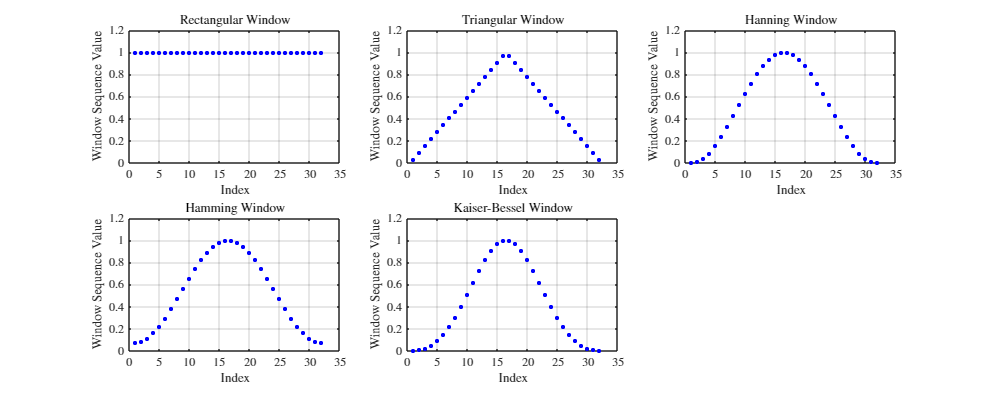

% Plot each original window sequence.
IndexVector = 1:1:N;
WindowSequences = [RectangularWindow, TriangularWindow, HanningWindow, HammingWindow, KaiserBesselWindow];
Title = {'Rectangular Window', 'Triangular Window', 'Hanning Window', 'Hamming Window', 'Kaiser-Bessel Window'};

figure('Position',[0 0 1500 600]);

for i = 1:size(WindowSequences,2)
    subplot(2,3,i);
    scatter(IndexVector, WindowSequences(:,i), 10, 'o', 'b', 'filled');
    grid on;
    box on;
    xlim([0 35]);
    xticks(0:5:35);
    ylim([0 1.2]);
    yticks(0:0.2:1.2);
    xlabel('Index');
    ylabel('Window Sequence Value');
    title(Title{i});
end

Figure 2-1. Original window sequences.

The original window sequences are zero-padded to the length of 256. Then their Discrete Fourier Transform (DFT) results are computed based on the Fast Fourier Transform (FFT) algorithm. The linear and logarithmic magnitudes of the DFT results are also computed.

% Input the length of the sequence after zero-padding.
N_fft = 256;

% Initialization for outputs.
PaddedWindowSequences = zeros(N_fft,size(WindowSequences,2)); 
Sequence_fft = zeros(N_fft,size(WindowSequences,2));
Sequence_fft_magnitude = zeros(N_fft,size(WindowSequences,2));
Sequence_fft_magnitude_dB = zeros(N_fft,size(WindowSequences,2));

% Calcuate the normalized linear/logarithmic magnitude for the window sequences after zero-padding.
for i = 1:size(WindowSequences,2)
    PaddedWindowSequences(:,i) = padarray(WindowSequences(:,i), N_fft-size(WindowSequences,1), 'post'); % Zero-pad the sequence.
    Sequence_fft(:,i) = fft(PaddedWindowSequences(:,i)); % Compute the DFT of the sequence using FFT.
    Sequence_fft_magnitude(:,i) = abs(Sequence_fft(:,i))/N; % Compute normalized linear magnitude of the Fourier coefficients.
    Sequence_fft_magnitude_dB(:,i) = 20 * log10(Sequence_fft_magnitude(:,i)); % Compute logarithmic magnitude in dB.
    Sequence_fft_magnitude_dB(:,i) = Sequence_fft_magnitude_dB(:,i) - max(Sequence_fft_magnitude_dB(:,i)); % Normalize the logrithmic magnitude.
end

The normalized linear and logarithmic magnitudes of the DFT results are plotted using the following code:

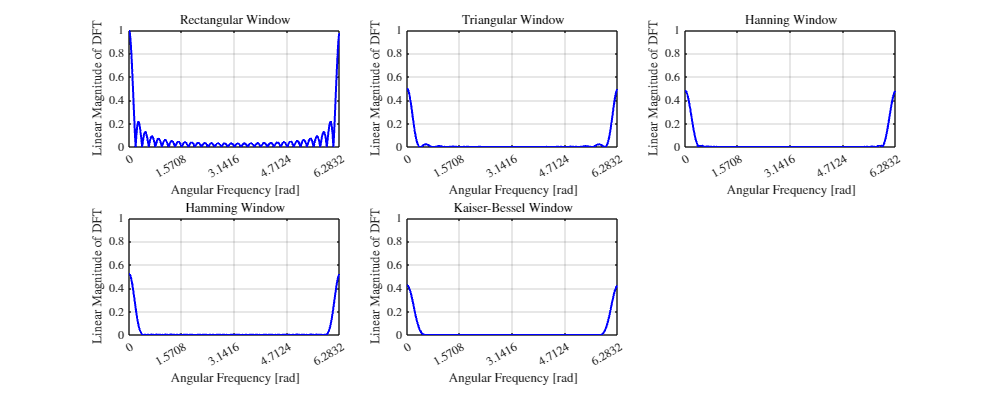

Frequency = (0:1:N_fft-1)/N_fft * (2*pi);

% Plot the linear magnitudes of the DFT results.
figure('Position',[0 0 1500 600]);

for i = 1:size(Sequence_fft_magnitude,2)
    subplot(2,3,i);
    plot(Frequency, Sequence_fft_magnitude(:,i), 'b', 'LineWidth', 1.5);
    grid on;
    box on;
    xlim([0 2*pi]);
    xticks(0:0.5*pi:2*pi);
    % xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
    ylim([0 1]);
    yticks(0:0.2:1);
    xlabel('Angular Frequency [rad]');
    ylabel('Linear Magnitude of DFT');
    title(Title{i});
end

Figure 2-2. Normalized linear magnitudes for the DFT results of the window sequences.

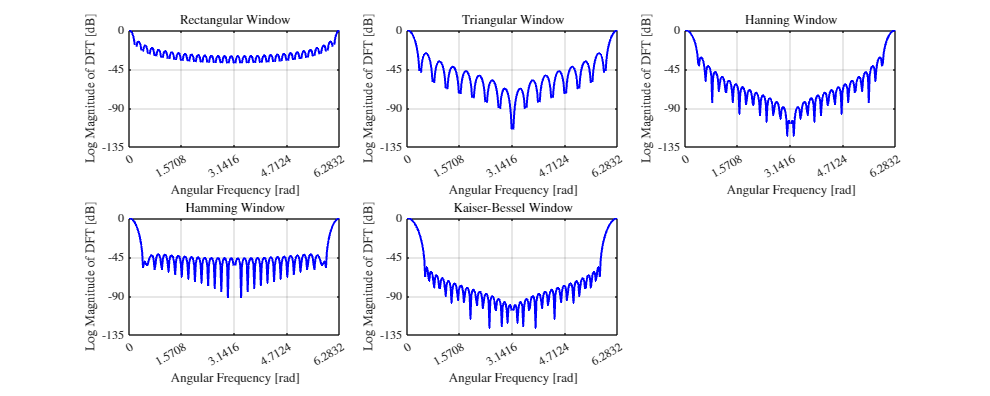

% Plot the logrithmic magnitudes of the DFT results.
figure('Position',[0 0 1500 600]);

for i = 1:size(Sequence_fft_magnitude_dB,2)
    subplot(2,3,i);
    plot(Frequency, Sequence_fft_magnitude_dB(:,i), 'b', 'LineWidth', 1.5);
    grid on;
    box on;
    xlim([0 2*pi]);
    xticks(0:0.5*pi:2*pi);
    % xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
    ylim([-135 0]);
    yticks(-135:45:0);
    xlabel('Angular Frequency [rad]');
    ylabel('Log Magnitude of DFT [dB]');
    title(Title{i});
end

Figure 2-3. Normalized logrithmic magnitudes for the DFT results of the window sequences.

#### Problem III.

% Initialization and default plot settings.
clear; clc; close all;

set(0, 'DefaultAxesFontSize', 10);
set(0, 'DefaultTextFontSize', 10);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');

A discrete-time signal *x*(*n*) is defined as the summation of two sinusoidal sequences 40 dB apart: 

 
$$x\left(n\right)=A_1 \cos \left(\omega_1 n+\varphi_1 \right)+A_2 \cos \left(\omega_2 n+\varphi_2 \right)$$


where $20\cdot \log \frac{A_1 }{A_2 }=40\;\mathrm{dB}$

The angular frequency of two sinusoidal sequences are bin centered as follows:


$$\omega_1 =\frac{2\pi }{N}k_1$$



$$\omega_2 =\frac{2\pi }{N}k_2$$


where $k=0,1,2\;\ldotp \ldotp \ldotp \frac{N}{2}-1$

It is assumed that the larger magnitude is $A_1 =1$. Therefore, the smaller amplitude is $A_2 =\frac{A_1 }{100}=0\ldotp 01$. Two cases for the separated frequencies are involved where $k_2 =16$ is fixed while $k_1 =10$ is considered as the case of 6-bin difference and  $k_1 =10\ldotp 5$ is considered as the case of 5.5-bin difference.

The spectral resolution capabilities of multiple windows are investigated including: (1) rectangular window, (2) triangular window, (3) Hanning window, (4) Hamming window, and (5) Kaiser-Bessel window (*α* = 2.5 or *β* = *πα* = 7.85). In this project, the sequence length, window length and FFT length are all defined as *N* = 256. For the sequences with each separated frequency (6-bin or 5.5-bin) windowed by a particular window, the normalized logarithmic magnitude of its Discrete Fourier Transform (DFT) is calculated based on the following steps:

- Window the original sequence.

- Calculate the Discrete Fourier Transform (DFT) of the windowed sequence based on the Fast Fourier Transform (FFT) algorithm.

- Calculate the logrithmic amplitude of the Fourier Transform result.

- Normalizet the logrithmic amplitude to make the peak amplitude at 0 dB.

The following code is adopted for the implementation of the steps above:

N = 256; % Sequence length = Window Length = FFT length = 256. 
A1 = 1; % Amplitude of x1.
A2 = 0.01; % Amplitude of x2 (x1 and x2 have 40 dB separation).

% Define the center of the bin.
k2 = 16;
k1_1 = k2 - 6; % 6-bin difference.
k1_2 = k2 - 5.5; % 5.5-bin difference.

omega2 = 2 * pi / N * k2;
omega1_1 = 2 * pi / N * k1_1;
omega1_2 = 2 * pi / N * k1_2;

% Define the signal (assume the phase angle phi1=phi2=0).
n = (0:1:N-1)'; % Index vector.

phi1 = 0;
phi2 = 0;

x1 = A1*cos(omega1_1*n+phi1) + A2*cos(omega2*n+phi2);
x2 = A1*cos(omega1_2*n+phi1) + A2*cos(omega2*n+phi2);

% Generate window sequences with the given sequence length N.
RectangularWindow = rectwin(N); % Rectangular window.
TriangularWindow = triang(N); % Triangular window.
HanningWindow = hann(N); % Hannning window.
HammingWindow = hamming(N); % Hamming window.
KaiserBesselWindow = kaiser(N, 7.85); % Kaiser-Bessel window (alpha = 2.5 or beta = alpha*pi = 7.85).

WindowSequences = [RectangularWindow, TriangularWindow, HanningWindow, HammingWindow, KaiserBesselWindow];
Title = {'Rectangular Window', 'Triangular Window', 'Hanning Window', 'Hamming Window', 'Kaiser-Bessel Window'};

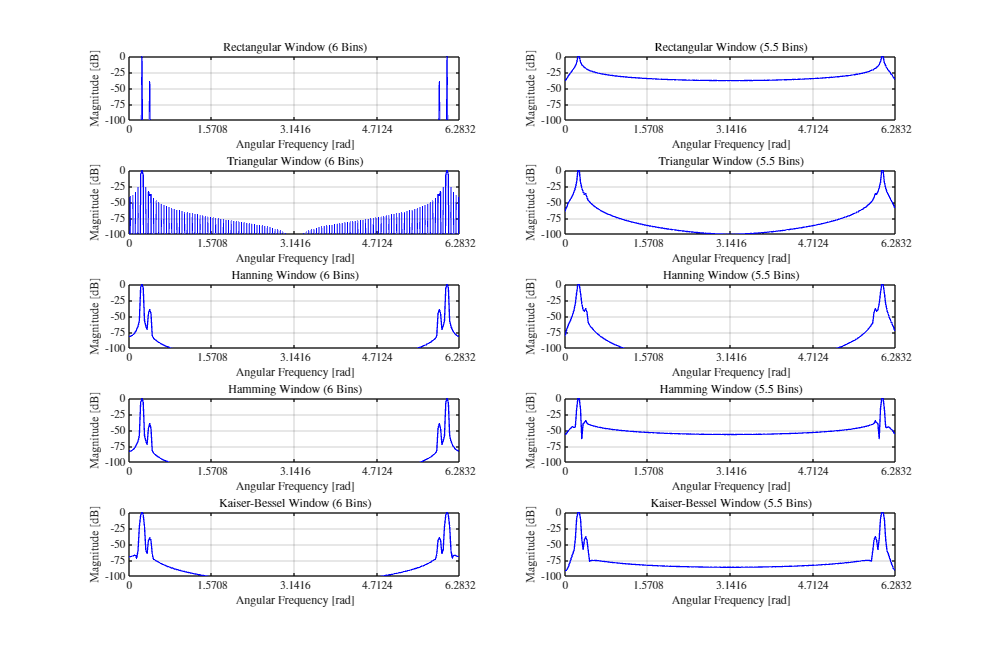

% Calculation and plot.
figure('Position',[0 0 1500 1000]);
Frequency = n/N * (2*pi);

for i = 1:size(WindowSequences,2)
    % Window the data.
    x1_windowed = x1 .* WindowSequences(:,i);
    x2_windowed = x2 .* WindowSequences(:,i);

    % Perform Fourier transform and calculate the logarithmic magnitude.
    x1_fft_magnitude = 20*log10(abs(fft(x1_windowed, N)));
    x2_fft_magnitude = 20*log10(abs(fft(x2_windowed, N)));
    
    % Normalized the results.
    x1_fft_magnitude = x1_fft_magnitude - max(x1_fft_magnitude);
    x2_fft_magnitude = x2_fft_magnitude - max(x2_fft_magnitude);

    % Plot the results.
    subplot(5,2,2*i-1);
    plot(Frequency, x1_fft_magnitude, 'b', 'LineWidth', 1);
    grid on;
    box on;
    xlim([0 2*pi]);
    xticks(0:0.5*pi:2*pi);
    % xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
    ylim([-100 0]);
    yticks(-100:25:0);
    xlabel('Angular Frequency [rad]');
    ylabel('Magnitude [dB]');
    title([Title{i}, ' (6 Bins)']);

    subplot(5,2,2*i);
    plot(Frequency, x2_fft_magnitude, 'b', 'LineWidth', 1);
    grid on;
    box on;
    xlim([0 2*pi]);
    xticks(0:0.5*pi:2*pi);
    % xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
    ylim([-100 0]);
    yticks(-100:25:0);
    xlabel('Angular Frequency [rad]');
    ylabel('Magnitude [dB]');
    title([Title{i}, ' (5.5 Bins)']);
end

Figure 3-1. Logarithmic magnitudes for the DFT results of the signal windowed by different windows.

The spectral resolution capability of a window is the ability to identify different frequency components in a signal in spectral analysis. It can be determined by observing the peaks in the spectrum that a more obvious peak represents that particular frequency component is more clearly identified from other frequency components.

For the case that two sinusoidal sequences separated in frequency by 6 bins, the rectangular window shows the best spectral resolution capability since the spectrum shows two clear peaks and almost no spectral leakage, where the higher peak represents the frequency component of $k_1 =10$ and the lower peak represents the frequency component of $k_2 =16$. The triangular window shows the worst spectral resolution capability. Multiple peaks are observed in its spectrum. Although the highest peak represents the frequency component of $k_1 =10$, there are multiple lower peaks and the frequency component of $k_2 =16$ can not be identified. Hanning window, Hamming window and Kaiser-Bessel windows show similar spectral resolution capability for this case. The two peaks can be observed in the spectrum, where the higher peak represents the frequency component of $k_1 =10$ and the lower peak represents the frequency component of $k_2 =16$. However, spectral leakage is also observed for these three windows.

For the case that two sinusoidal sequences separated in frequency by 5.5 bins, spectral leakage is observed in the spectrum for all the five windows. Kaiser-Bessel window is the only window where both of the frequency components can be clearly identified. For the other four window, although the frequency component of $k_1 =10\ldotp 5$ can be observed as the highest peak in the spectrum, the frequency component of $k_2 =16$ provides either no peak or unclear peak in the spectrum. The rank for the spectral resolution of these four windows for this case are listed in an descending order as follows: (1) Hamming window, (2) Hanning window, (3) triangular window, (4) rectangular window.

In summary, Kaiser-Bessel window has the best spectral resolution considering both cases in the analysis.